**Question 1**: Repeat this exercise with the coordinates p and q set to (5, 9), (9, 5), (17, 9), (17, 121), (5, 1) and (125, 1) respectively. What do you observe?

fprintf("%d, %d", 5,9)

5, 9

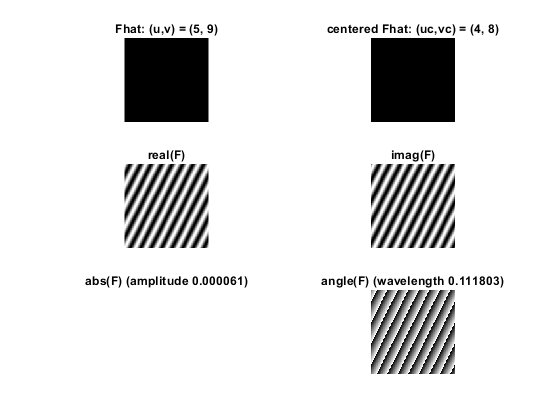

fftwave(5,9);

fprintf("%d, %d", 9,5)

9, 5

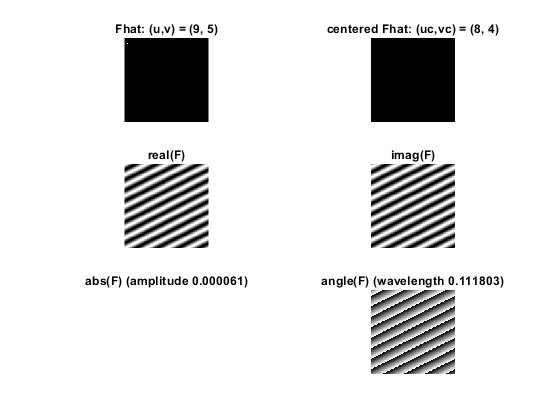

fftwave(9,5);

fprintf("%d, %d", 17,9)

17, 9

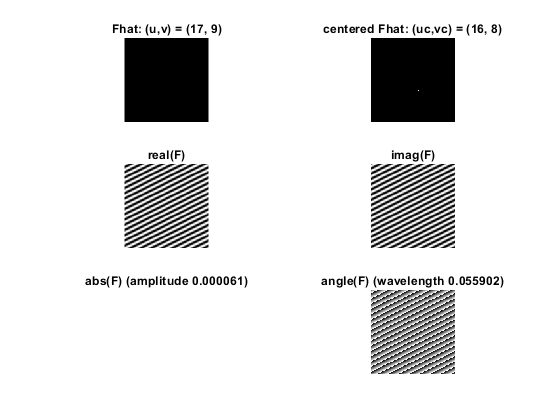

fftwave(17,9);

fprintf("%d, %d", 17,121)

17, 121

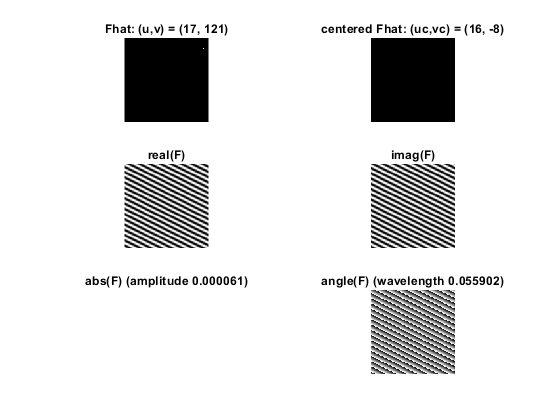

fftwave(17,121);

fprintf("%d, %d", 5,1)

5, 1

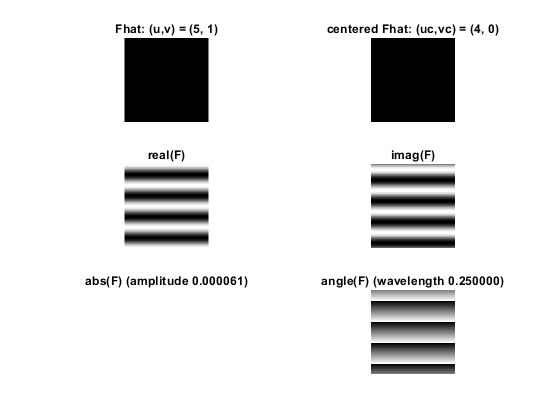

fftwave(5,1);

fprintf("%d, %d", 125,1)

125, 1

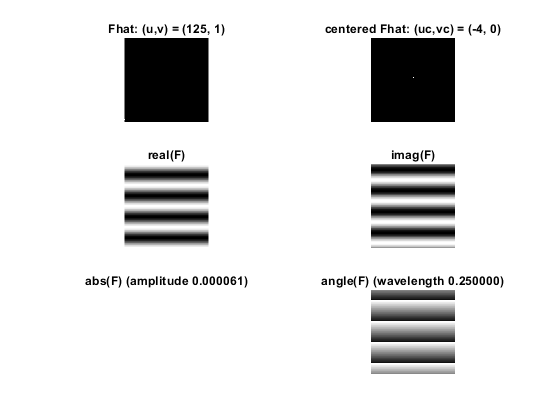

fftwave(125,1);

We use these pictures to answer questions 1-6.

**Code used for 1.4:**

fprintf("Section 1.4:")

Section 1.4:

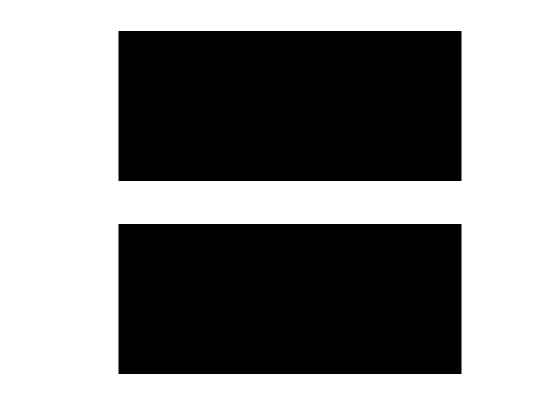

figure();
F = [zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;
showgrey(F);

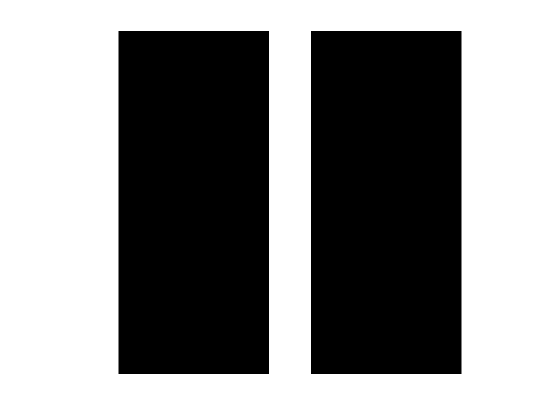

showgrey(G);

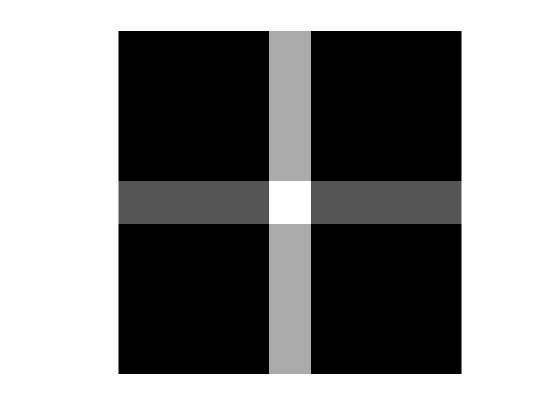

showgrey(H);

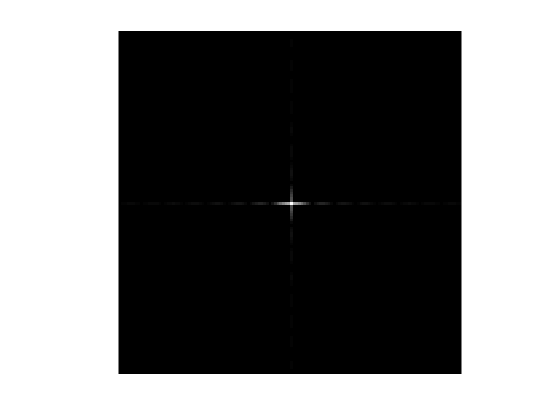

Fhat = fft2(F); 
Ghat = fft2(G);
Hhat = fft2(H);

showgrey(abs(fftshift(Hhat)));

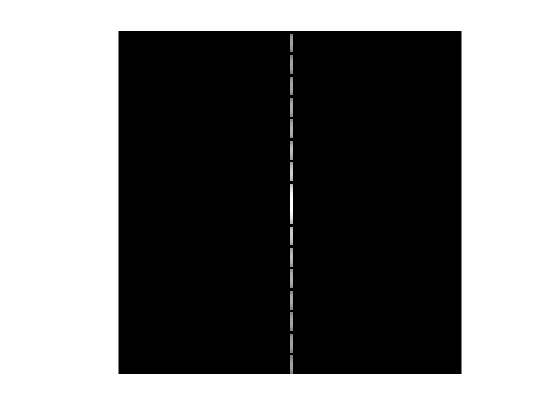

showgrey(log(1+abs(fftshift(Fhat))));

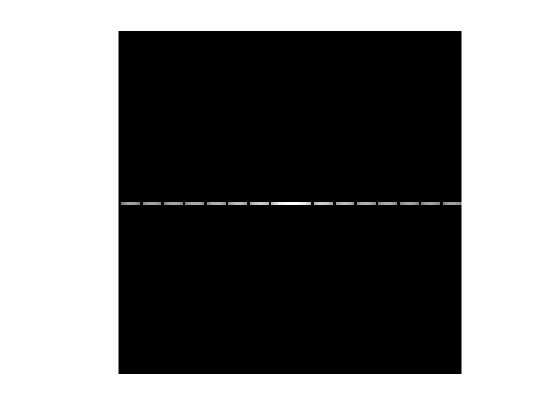

showgrey(log(1+abs(fftshift(Ghat))));

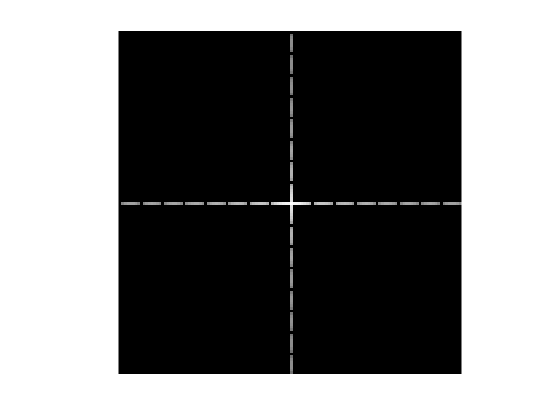

showgrey(log(1+abs(fftshift(Hhat))));

showgrey(log(1 + abs(fftshift(Fhat + 2*Ghat))));


% Check if ft is linear transform
all(all(Fhat + 2*Ghat == Hhat))

ans = logical
   1


**Code used for 1.5:**

fprintf("Section 1.5:")

Section 1.5:

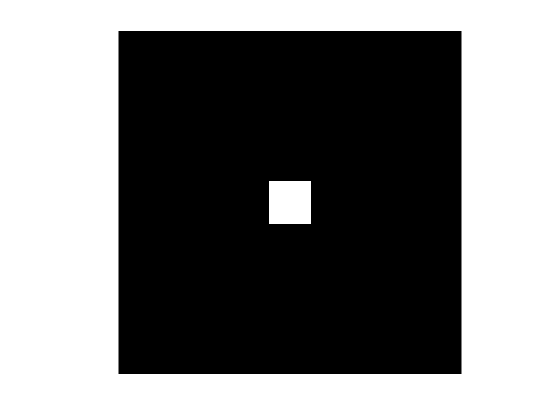

figure();
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
showgrey(F .* G); 

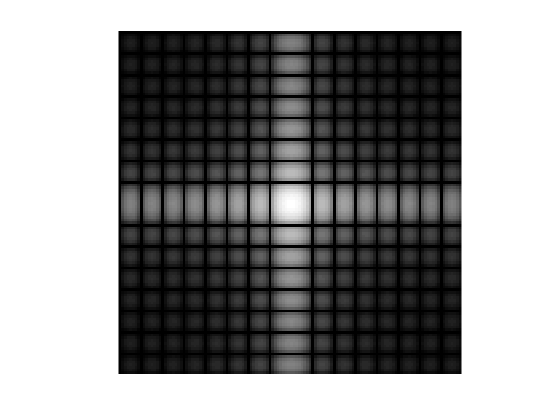

showfs(fft2(F .* G))

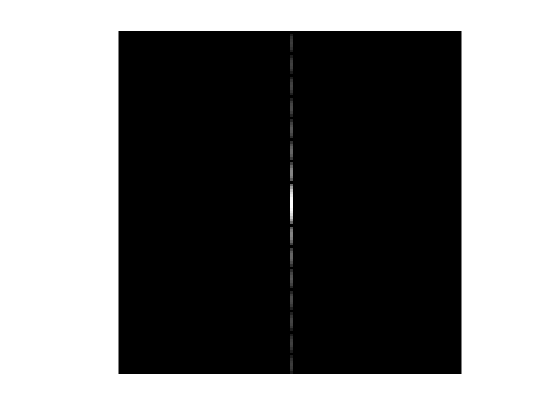


Fhat = 1/128.*(fft2(F));
Ghat = 1/128.*(fft2(G));
showfs(Fhat);

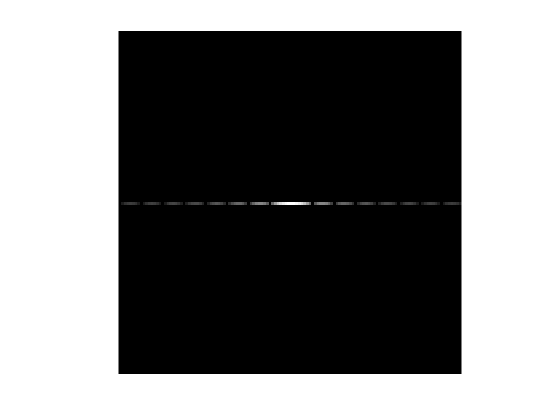

showfs(Ghat);

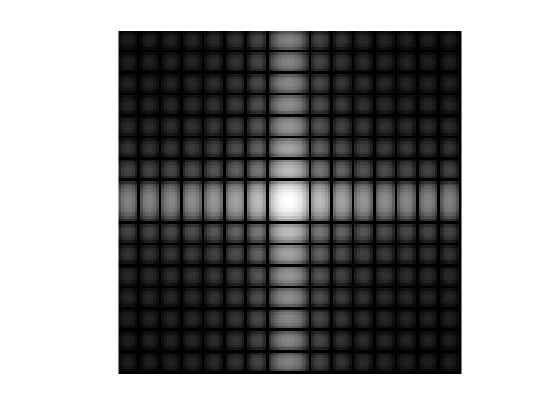

convd = fftshift(filter2(fftshift(Fhat), fftshift(Ghat)));
showfs(convd)

**Code used for 1.6-7:**

fprintf("Section 1.6-7:")

Section 1.6-7:

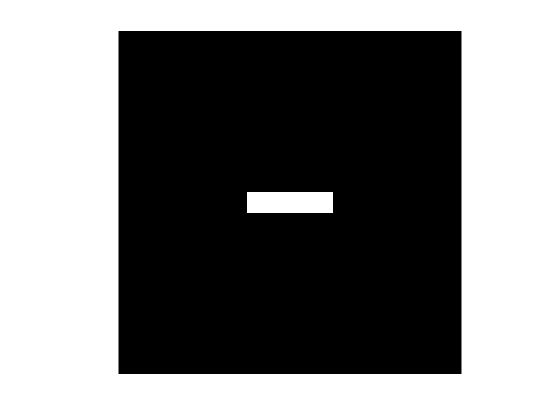

figure();
F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ... 
    [zeros(128, 48) ones(128, 32) zeros(128, 48)];

showgrey(F);

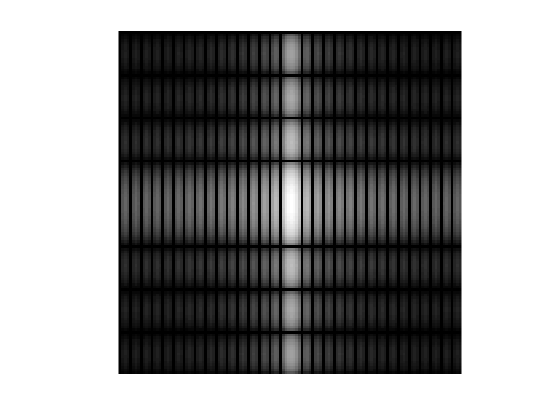


Fhat = fft2(F);
showfs(Fhat)

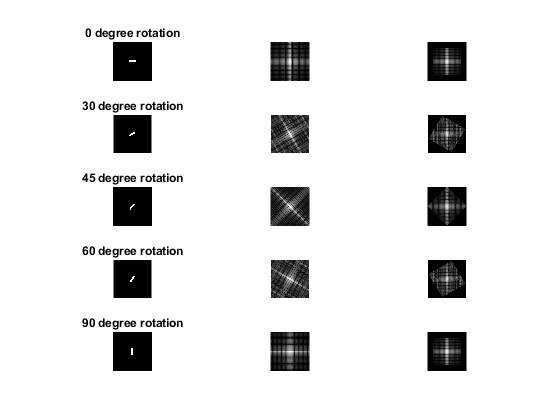


figure();
axis on;

alphas = [0,30, 45, 60, 90];
imageCount = 1;
for i = 1:5
    subplot(5,3,imageCount);
    G = rot(F,alphas(i));
    Ghat = fft2(G);
    showgrey(G)
    title(sprintf('%d degree rotation',alphas(i)));
    imageCount=imageCount+1;
    subplot(5,3,imageCount);
    showfs(Ghat);
    imageCount=imageCount+1;
    subplot(5,3,imageCount);
    Hhat = rot(fftshift(Ghat),-alphas(i));
    showgrey(log(1+abs(Hhat)));
    imageCount=imageCount+1;
end

**Code used for 1.8:**

fprintf("Section 1.8:")

Section 1.8:

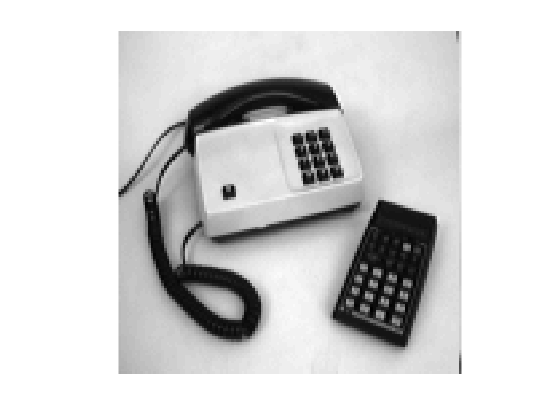

figure()
images = {phonecalc128, few128, nallo128};
i = 1;
showgrey(images{1})

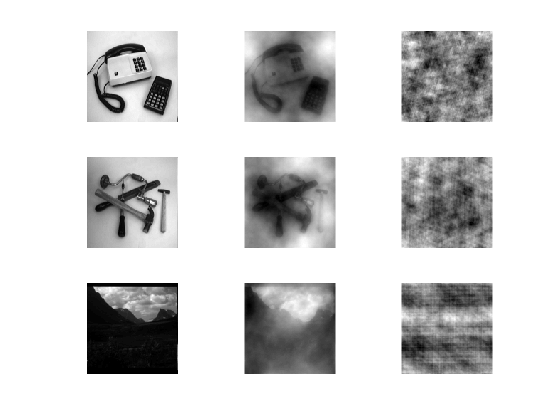

for j = 1:length(images)
    subplot(3,3,i)
    i = i+1;
    showgrey(images{j});
    subplot(3,3,i)
    i = i+1;
    showgrey(pow2image(images{j},1e-10));
    subplot(3,3,i);
    i = i+1;
    showgrey(randphaseimage(images{j}));
end

**Code used for 2.1-3:**

fprintf("Section 2.1-3:")

Section 2.1-3:

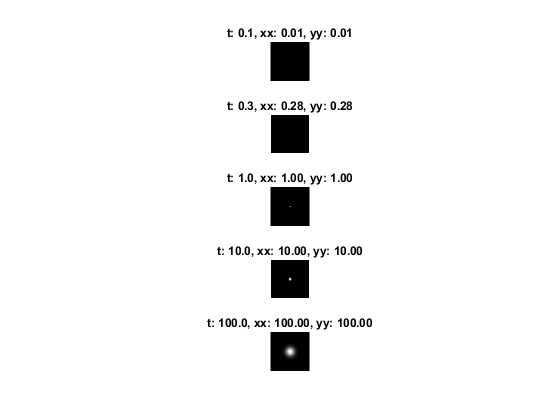

ts = [0.1, 0.3, 1.0, 10.0, 100.0];
figure()
for i = 1:length(ts)
    subplot(length(ts),1,i)
    psf = gaussfft(deltafcn(128,128), ts(i));
    filtVar = variance(psf);
    showgrey(psf)
    title(sprintf('t: %0.1f, xx: %0.2f, yy: %0.2f',ts(i),filtVar(1,1), filtVar(2,2)))
end

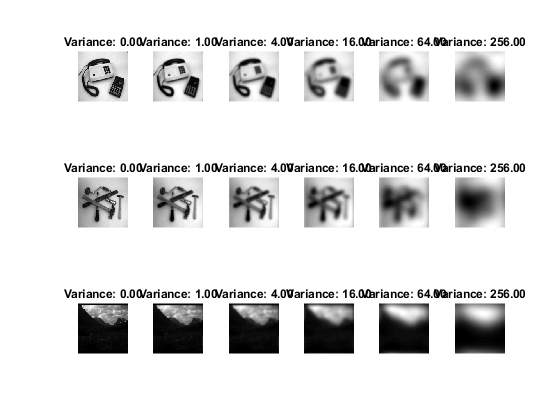

%16 ------
figure()
pics = {phonecalc128, few128, nallo128};
ts = [0.000001, 1.0, 4.0, 16.0, 64.0, 256.0];
counter = 1;
for p = 1:length(pics)
    for t = 1:length(ts)
        subplot(length(pics),length(ts),counter);
        psf = gaussfft(pics{p}, ts(t));
        showgrey(psf);
        title(sprintf('Variance: %0.2f', ts(t)));
        counter = counter + 1;
    end
end

**Code used for 3.1:**

fprintf("Section 3.1:")

Section 3.1:

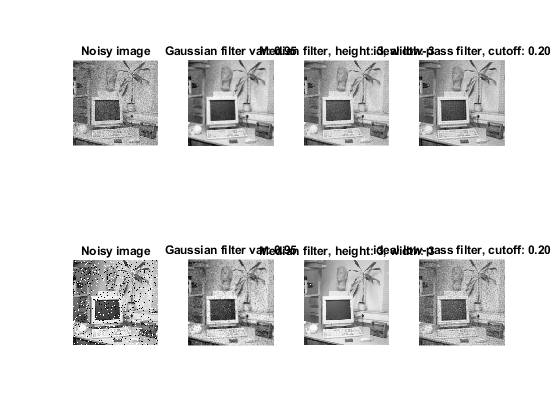

figure();
office = office256;
base = {gaussnoise(office,16), sapnoise(office,0.1,255)};
c = 1;
for b = 1:length(base)
    subplot(2,4,c);
    showgrey(base{b});
    title("Noisy image");
    subplot(2,4,c+1);
    var = 0.95;
    showgrey(gaussfft(base{b},var));
    title(sprintf("Gaussian filter var: %0.2f",var));
    subplot(2,4,c+2);
    wheight = 3;
    wwidth = 3;
    showgrey(medfilt(base{b},wheight,wwidth));
    title(sprintf("Median filter, height: %d, width: %d",wheight, wwidth));
    subplot(2,4,c+3);
    cutoff = 0.2;
    showgrey(ideal(base{b},cutoff));
    title(sprintf("ideal low-pass filter, cutoff: %0.2f", cutoff));
    c = c + 4;
end

**Code for section 3.2:**

fprintf("Section 3.2:")

Section 3.2:

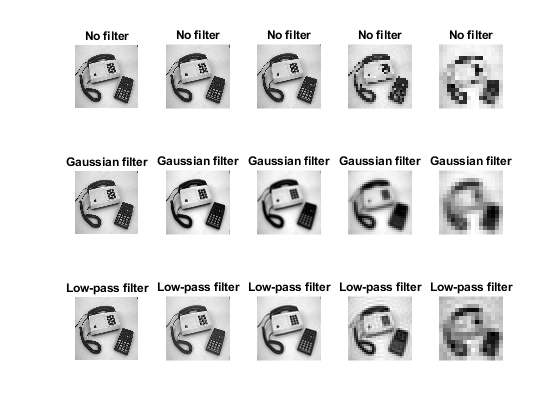

%gaussian
img = phonecalc256;
gaussfilter = @(pic)gaussfft(pic,1);
lpfilter = @(pic)ideal(pic,60/256);
subsample(img,gaussfilter, lpfilter);